# Main Document

*Authors:* Lili Baker, Olivia Chang, Tyler Ewald

*Learning Objectives:* As a result of working through this notebook, you will learn:

- put our learning objectives here

## Model Baseline

- Excludes vaccinations

- Assumes immunity is lost after a period of time

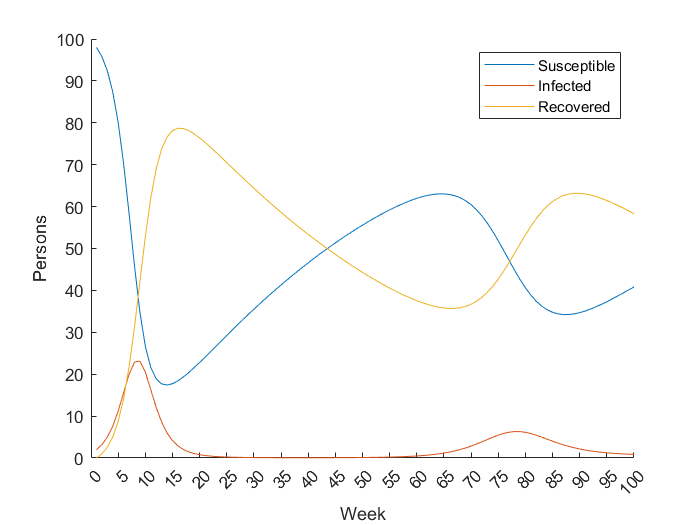

% Setup
num_steps = 100;
axis_tick_interval = 5; 

% Define flow parameters
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / week)
alpha = 0; % assume 0% of people are getting vaccinated in a given week
omega = 1 / 52; % assume 10% of people become susceptible after recovering
% omega should be 1 / time to lose immunity
% in training data: approx 52 weeks (can assume this is a year)

% Define initial state
% TODO: at some point pull this from training data instead of hardcoding
% them
i_0 = 2;       % Initial count of infected persons
s_0 = 100 - i_0;
r_0 = 0;

[S, I, R, W] = sir_vaccine(s_0, i_0, r_0, beta, gamma, alpha, omega, num_steps);

% Plot graph
figure(1); clf; hold on;
xticks(0:axis_tick_interval:num_steps); % add axis ticks
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

## Vaccination Model

- Includes vaccinations

- Assumes immunity is lost after a period of time

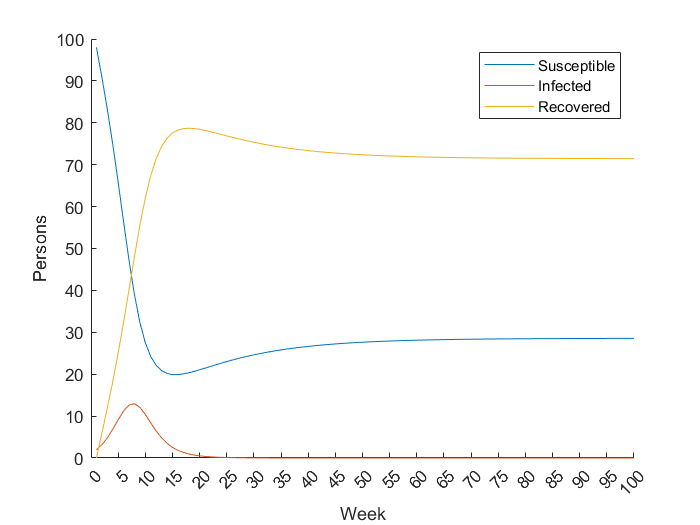

% Setup
num_steps = 100;
axis_tick_interval = 5; 

% Define flow parameters
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / week)
alpha = 0.05; % assume 5% of people are getting vaccinated in a given week
omega = 1 / 50; % assume 10% of people become susceptible after recovering
% omega should be 1 / time to lose immunity
% in training data: approx 50 weeks (can assume this is a year)

% Define initial state
% TODO: at some point pull this from training data instead of hardcoding
% them
i_0 = 2;       % Initial count of infected persons
s_0 = 100 - i_0;
r_0 = 0;

[S, I, R, W] = sir_vaccine(s_0, i_0, r_0, beta, gamma, alpha, omega, num_steps);

% Plot graph
figure(1); clf; hold on;
xticks(0:axis_tick_interval:num_steps); % add axis ticks
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})